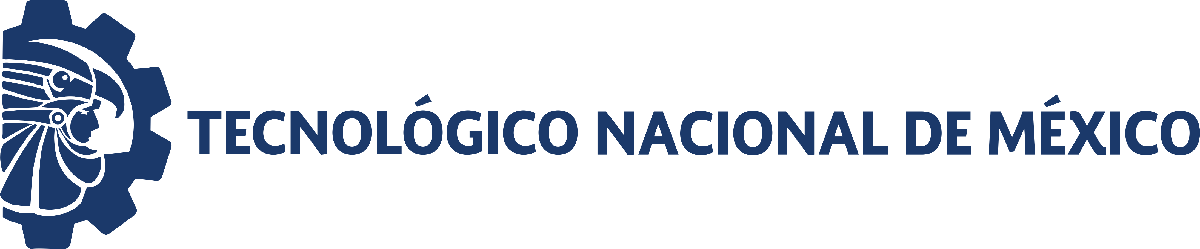                                 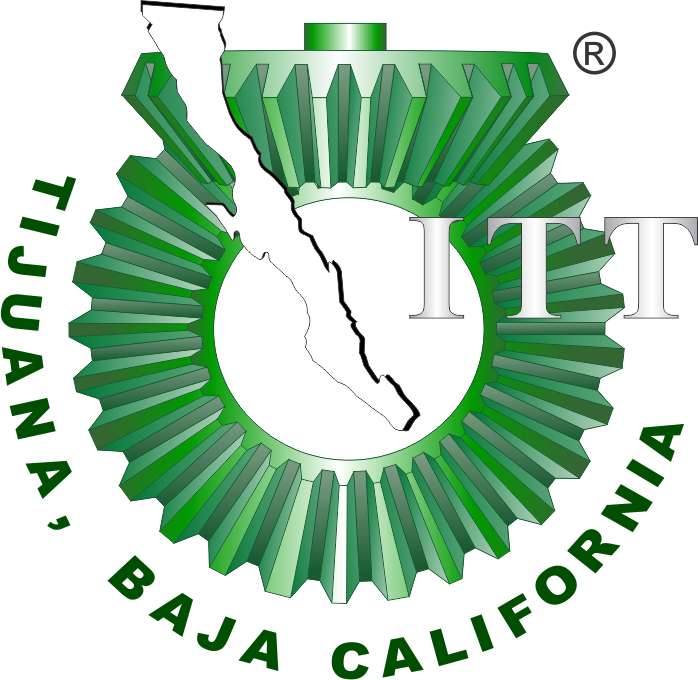

# Práctica 3: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                                                                    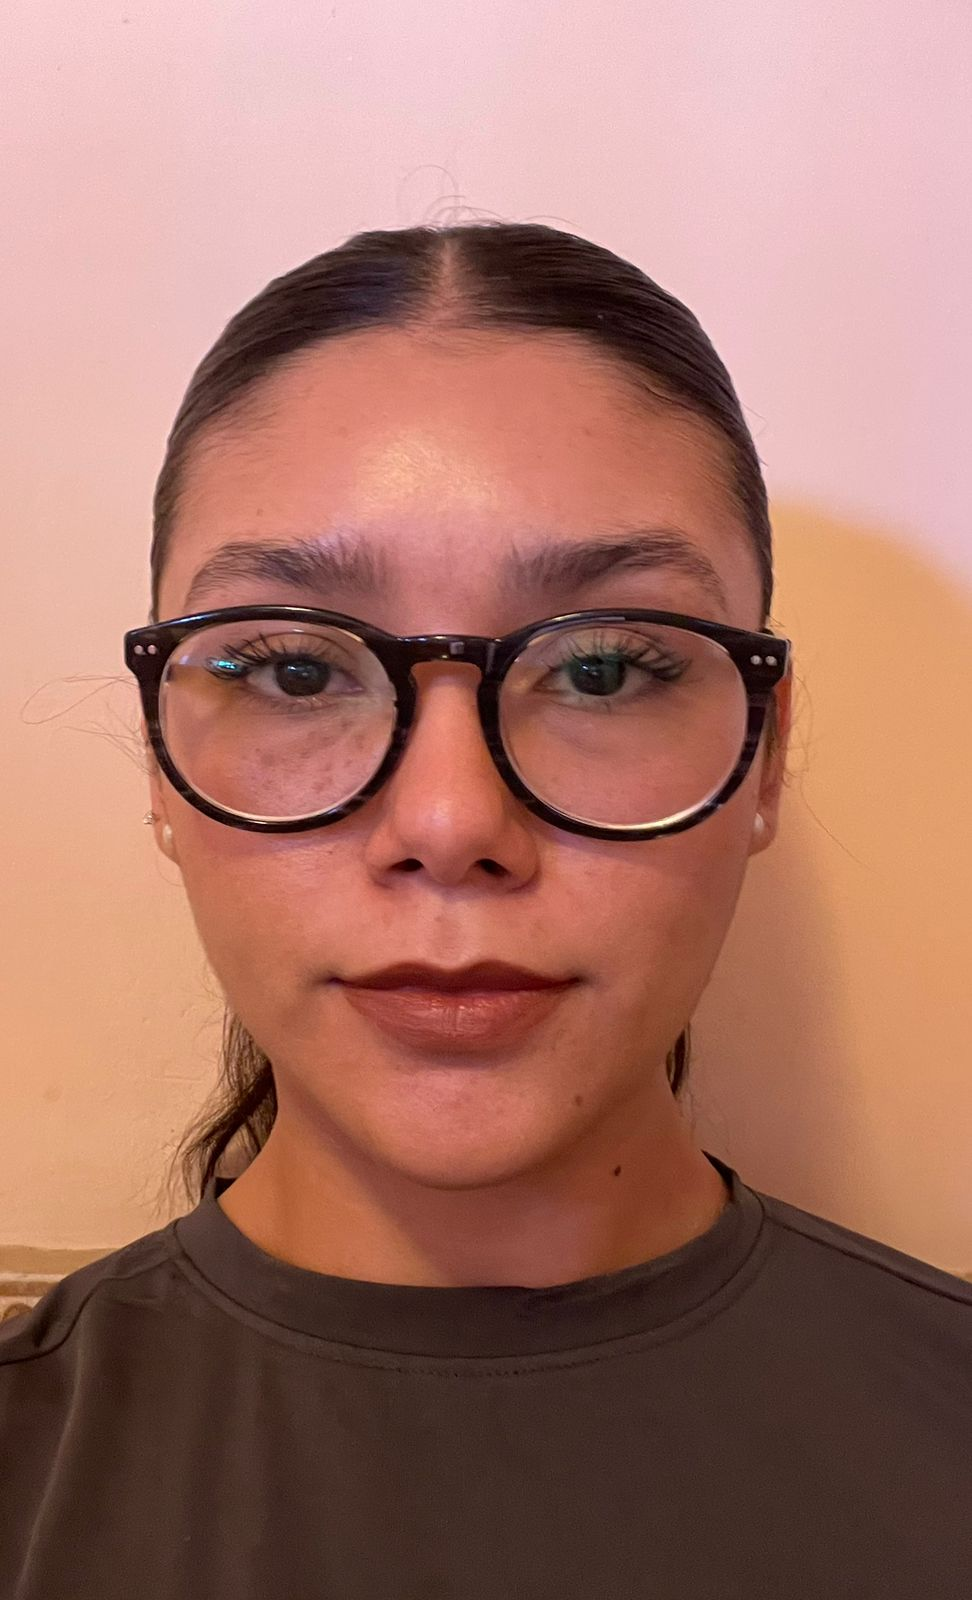

Nombre del alumno: **Maria Belen Galindo Ramirez **

Número de control: **22211755**

Correo institucional: **l22211755@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

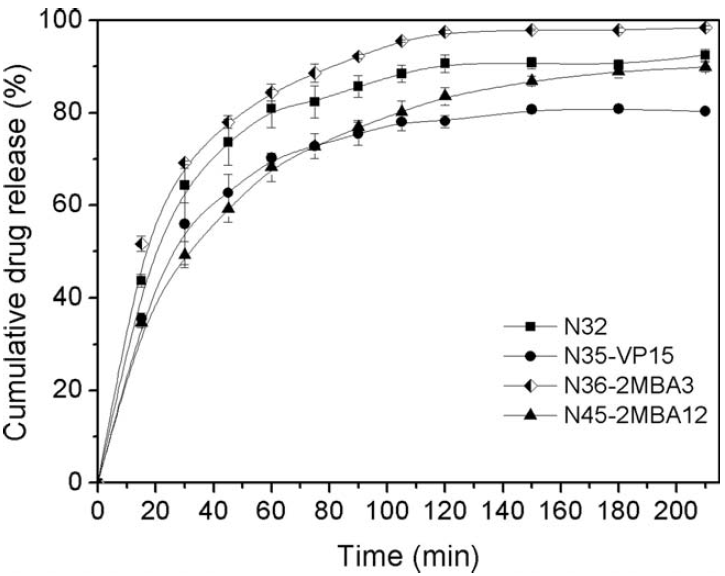

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $x\left(t\right)=\rho_1 \sqrt{t}+\rho_2 t$

EureqaODE: $\frac{\mathrm{dx}}{\mathrm{dt}}=\rho_1 -\rho_2 t$

## Datos experimentales

clc; clear; close all; warning('off','all')
[t,x1,x2,x3,x4] = getdata('data.csv'); plotdata(t,x1,x2,x3,x4);

    t [min]     N45       N32       N35       N36  
    _______    ______    ______    ______    ______

        0           0         0         0         0
       15      34.698     43.95    35.587    51.601
       30      49.288    64.413    55.872    69.039
       45      59.253    73.488    62.633     77.58
       60      68.327    80.961    70.285    83.986
       75      72.598    82.206    72.776    88.434
       90      76.868    85.587    75.445    91.993
      105      80.249    88.434    77.936    95.374
      120       83.63    90.569    78.292    97.509
      150      87.011    90.747    80.783    97.687
      180       88.79    90.036    80.961    97.509
      210       89.68    92.349    80.427    98.221



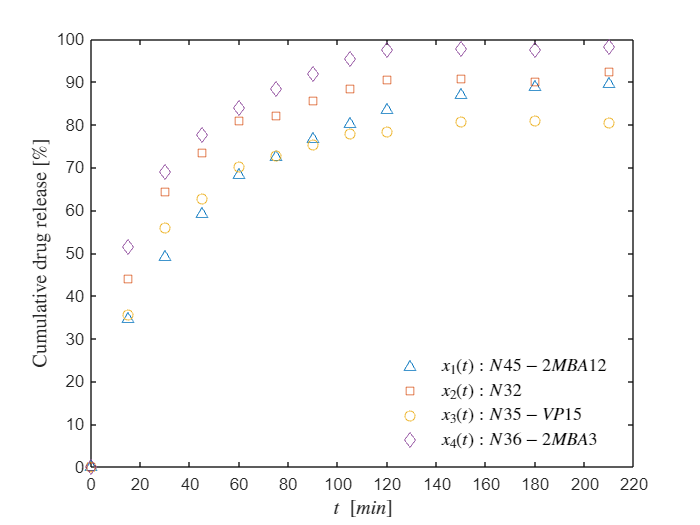


exportgraphics(gcf,'data.pdf','ContentType','vector')

## Regresión no lineal, bioestadísticos y experimentación in silico 

labels = {'x1(t):N45-2MBA12','x2(t):N32','x3(t):N35-VP15','x4(t):N36-2MBA3'};
xo = [x1, x2, x3, x4]; s = size(xo);

### Función Peppas 

n0 = 0.1; k0 = 0.1; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[n0;k0]);
    xp(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

      {'k'}        17.786       2.1859      4.8705    12.915     22.656    1.0149e-05
      {'n'}       0.31525     0.026184    0.058343    0.2569    0.37359    2.8327e-07

R-cuadrada ordinaria: 0.97973
Suma residual de cuadrados: 159.3817
Criterio de información de Akaike ajustado: 70.4246


    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate      SE         MoE              CI95             Pvalue  
    __________    ________    _______    ________    __________________    __________

      {'k'}        30.751        4.28      9.5365     21.215     40.288     2.979e-05
      {'n'}        0.2178     0.03013    0.067134    0.15067    0.28494    2.8282e-05

R-cuadrada ordinaria: 0.96361
Suma residual de cuadrados: 293.8837
Criterio de información de Akaike ajustado: 77.7672


    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.738       3.8195      8.5103     16.228     33.249    7.1008e-05
      {'n'}       0.23625     0.033316    0.074233    0.16202    0.31049    3.3297e-05

R-cuadrada ordinaria: 0.95841
Suma residual de cuadrados: 268.5115
Criterio de información de Akaike ajustado: 76.6837


    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        34.175       3.8328      8.5399     25.635     42.715    4.4991e-06
      {'n'}        0.2103     0.024311    0.054168    0.15613    0.26447    5.8995e-06

R-cuadrada ordinaria: 0.97536
Suma residual de cuadrados: 222.9063
Criterio de información de Akaike ajustado: 74.45


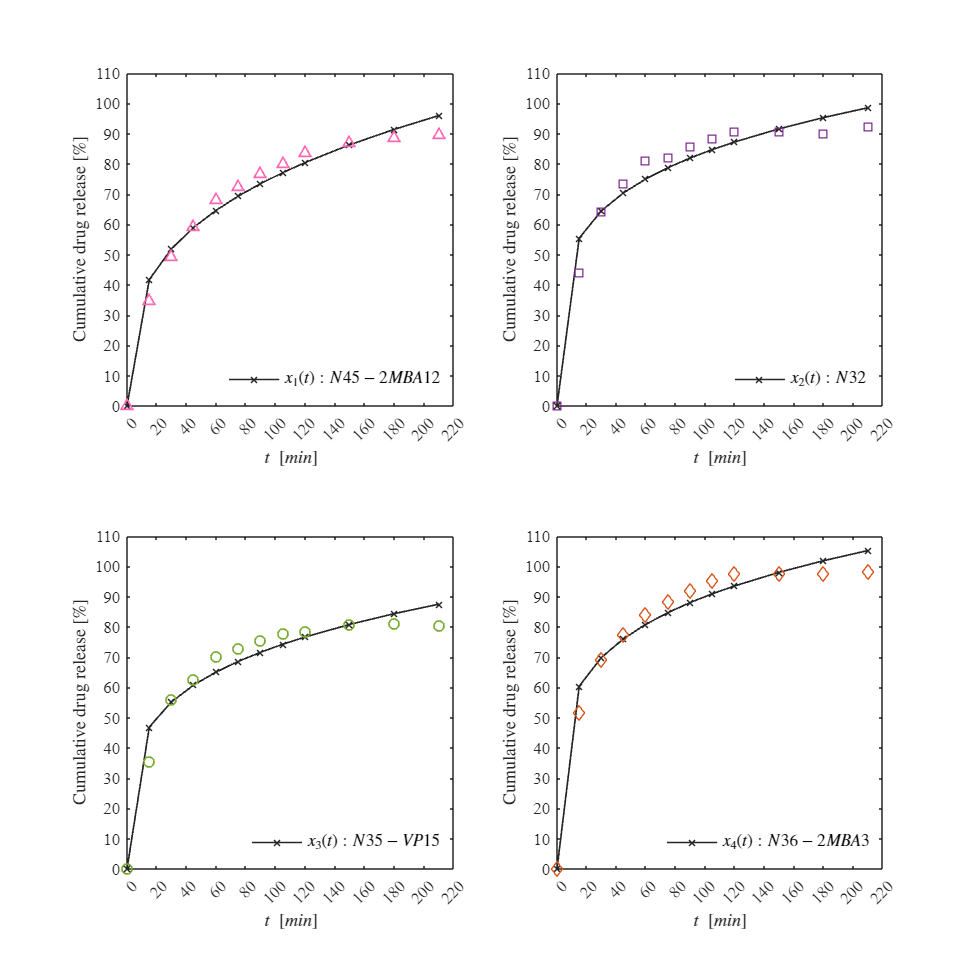

plotresults(t,xo,xp); exportgraphics(gcf,'peppas.pdf','ContentType','vector')

### Función farmacocinética de primer orden 

beta0 = 100; k0 = 0.02; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ',string(labels(i))]);
    mdl = farmacocinetica(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       87.694        1.476       3.2888      84.405      90.982    4.4337e-14
     {'k'   }     0.026101    0.0015541    0.0034628    0.022638    0.029564     1.175e-08

R-cuadrada ordinaria: 0.99083
Suma residual de cuadrados: 72.1353
Criterio de información de Akaike ajustado: 60.9115


    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'beta'}       89.777      0.84245      1.8771        87.9      91.654    1.2977e-16
     {'k'   }     0.040714    0.0018055    0.004023    0.036691    0.044737    6.6208e-10

R-cuadrada ordinaria: 0.99511
Suma residual de cuadrados: 39.4755
Criterio de información de Akaike ajustado: 53.6771


    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'beta'}       79.588      0.67724       1.509      78.079      81.097    4.8817e-17
     {'k'   }     0.037278    0.0014164    0.003156    0.034122    0.040434    1.4451e-10

R-cuadrada ordinaria: 0.99636
Suma residual de cuadrados: 23.4733
Criterio de información de Akaike ajustado: 47.4394


    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}      95.946        1.3884       3.0935      92.852      99.039    9.8107e-15
     {'k'   }     0.04192     0.0029207    0.0065078    0.035412    0.048428    5.3384e-08

R-cuadrada ordinaria: 0.98784
Suma residual de cuadrados: 109.997
Criterio de información de Akaike ajustado: 65.9744


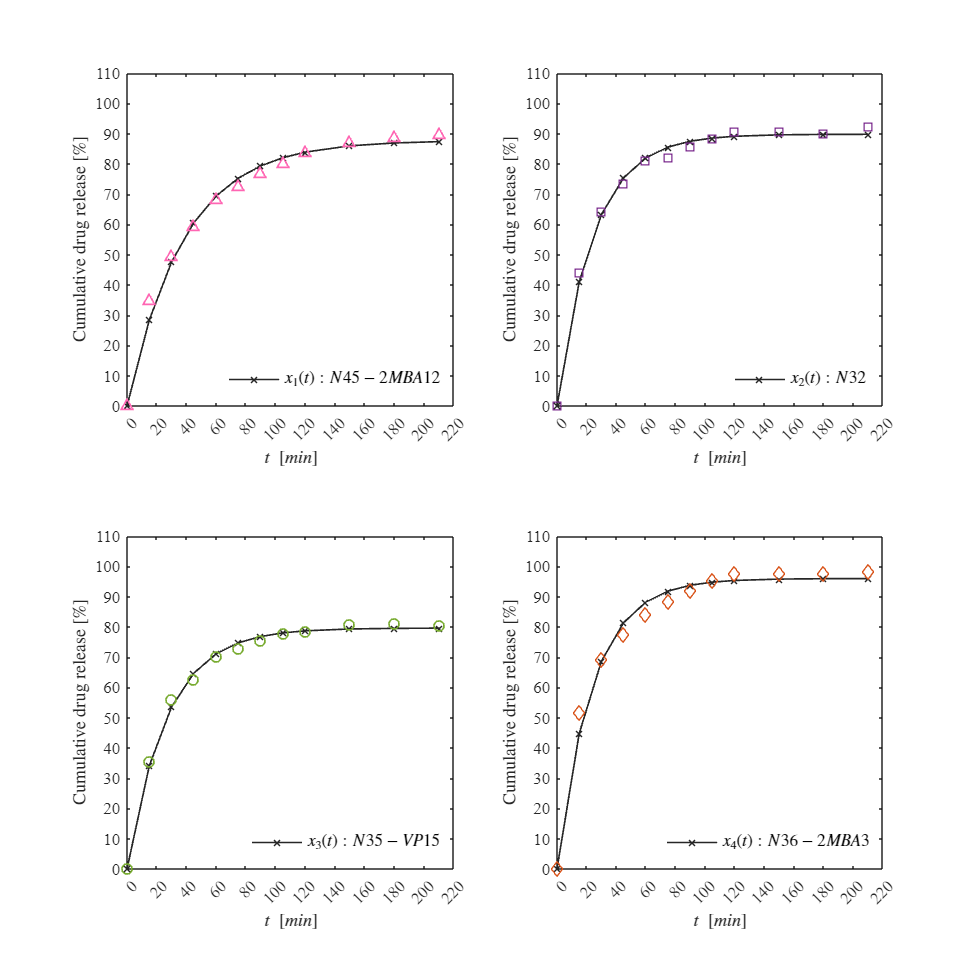

plotresults(t,xo,xfc); exportgraphics(gcf,'farmacocinetica.pdf','ContentType','vector')

###  Eureqa: Función del tiempo

rho1 = 11.7; rho2 = 0.372; xe1 = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ',string(labels(i))]);
    mdl = eureqa(t,xo(:,i),[rho1;rho2]);
    xe1(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE               CI95              Pvalue  
    __________    ________    ________    ________    ____________________    __________

     {'rho1'}       11.217     0.22708     0.50597      10.711      11.723    2.7924e-13
     {'rho2'}     -0.33917    0.019605    0.043682    -0.38285    -0.29549    8.8121e-09

R-cuadrada ordinaria: 0.9963
Suma residual de cuadrados: 29.1313
Criterio de información de Akaike ajustado: 50.0307


    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate      SE         MoE               CI95              Pvalue  
    __________    ________    _______    ________    ____________________    __________

     {'rho1'}       14.578    0.26294     0.58586      13.992      15.164     8.835e-14
     {'rho2'}     -0.57653     0.0227    0.050579    -0.62711    -0.52595    2.0536e-10

R-cuadrada ordinaria: 0.99516
Suma residual de cuadrados: 39.057
Criterio de información de Akaike ajustado: 53.5492


    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE               CI95              Pvalue  
    __________    ________    ________    ________    ____________________    __________

     {'rho1'}       12.484     0.27195     0.60594      11.878       13.09    5.7941e-13
     {'rho2'}     -0.47881    0.023478    0.052313    -0.53113     -0.4265    1.7733e-09

R-cuadrada ordinaria: 0.99353
Suma residual de cuadrados: 41.7807
Criterio de información de Akaike ajustado: 54.3582


    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE               CI95              Pvalue  
    __________    ________    ________    ________    ____________________    __________

     {'rho1'}       15.691     0.12826     0.28578      15.405      15.977    3.2672e-17
     {'rho2'}     -0.62285    0.011073    0.024672    -0.64752    -0.59818    7.6493e-14

R-cuadrada ordinaria: 0.99897
Suma residual de cuadrados: 9.2934
Criterio de información de Akaike ajustado: 36.3207


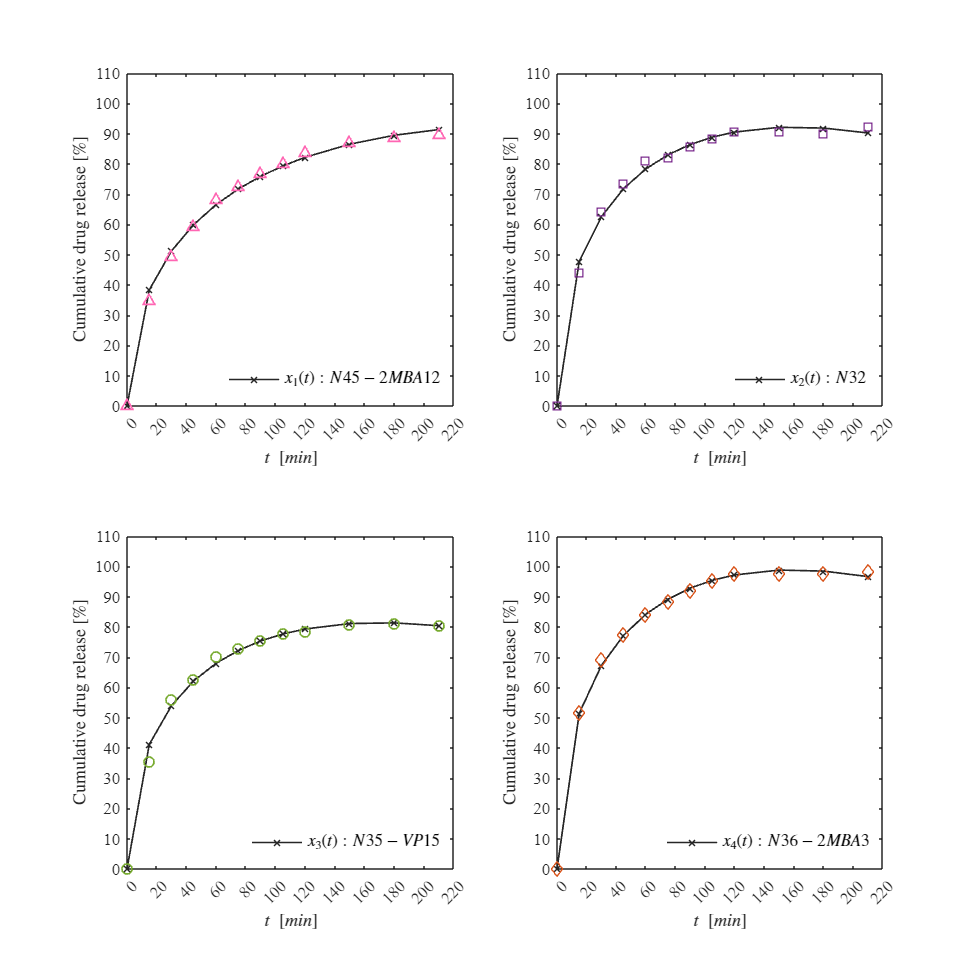

plotresults(t,xo,xe1); exportgraphics(gcf,'eureqa.pdf','ContentType','vector')

###  Eureqa: Función del tiempo diferencial

rho1 = 2.3; rho2 = 0.0259; xe2 = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ',string(labels(i))]);
    mdl = eureqaD(t,xo(:,i),[rho1;rho2]);
    xe2(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE              CI95              Pvalue  
    __________    ________    ________    _________    ___________________    __________

     {'rho1'}      2.3652      0.14119      0.31459     2.0506      2.6798    1.2043e-08
     {'rho2'}     0.02681     0.001988    0.0044296    0.02238    0.031239    9.6798e-08

R-cuadrada ordinaria: 0.98949
Suma residual de cuadrados: 82.6605
Criterio de información de Akaike ajustado: 62.5459


    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'rho1'}       4.2276      0.28257      0.6296       3.598      4.8572    3.5843e-08
     {'rho2'}     0.047062    0.0034132    0.007605    0.039457    0.054667    7.8329e-08

R-cuadrada ordinaria: 0.99499
Suma residual de cuadrados: 40.4694
Criterio de información de Akaike ajustado: 53.9755


    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       3.2944      0.16026      0.35707      2.9373      3.6514    1.6404e-09
     {'rho2'}     0.041352    0.0022396    0.0049901    0.036362    0.046343    4.6791e-09

R-cuadrada ordinaria: 0.99612
Suma residual de cuadrados: 25.0357
Criterio de información de Akaike ajustado: 48.2126


    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'rho1'}       4.7491      0.54856      1.2223      3.5268      5.9714    5.8581e-06
     {'rho2'}     0.049478    0.0061406    0.013682    0.035796     0.06316    1.1058e-05

R-cuadrada ordinaria: 0.98769
Suma residual de cuadrados: 111.4106
Criterio de información de Akaike ajustado: 66.1277


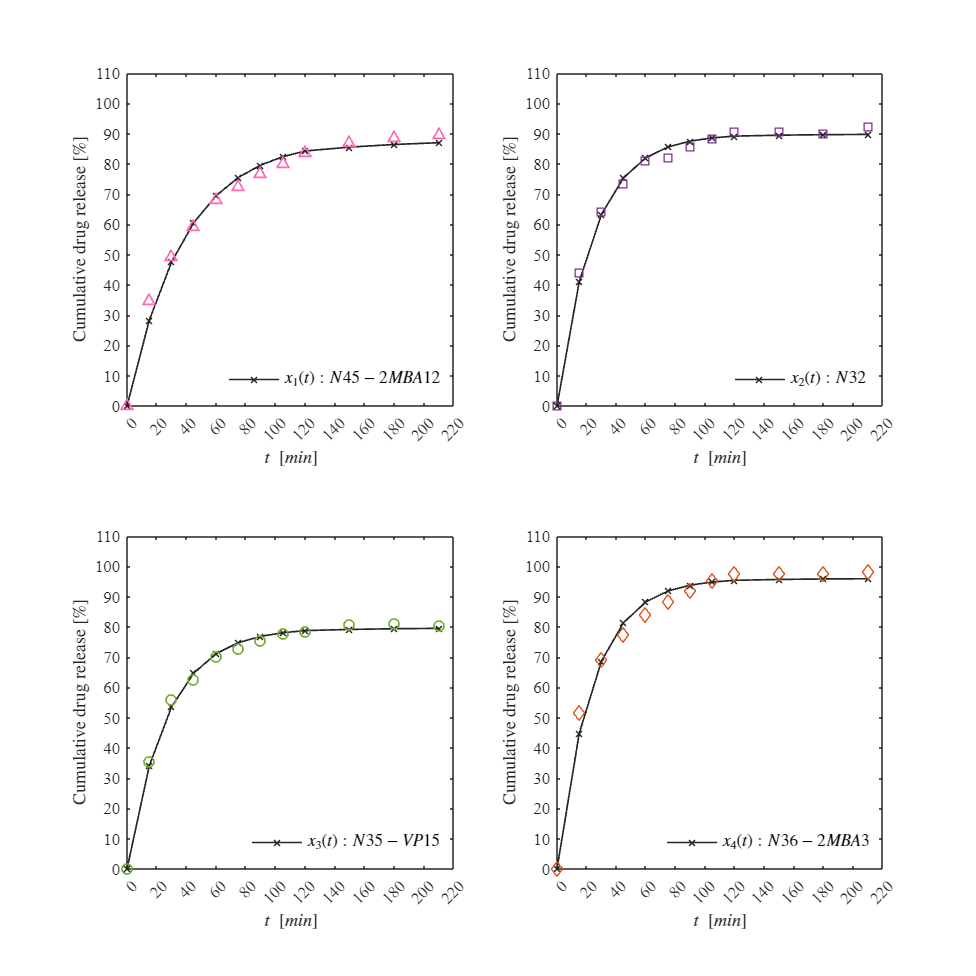

plotresults(t,xo,xe2 ...
    ...
    ); exportgraphics(gcf,'eureqaODE.pdf','ContentType','vector')

## Funciones

### Datos experimentales 

function [t, x1, x2, x3, x4] = getdata(filename)
    data = readmatrix(filename);

    t  = data(:, 1);
    x1 = data(:, 2);
    x2 = data(:, 3);
    x3 = data(:, 4);
    x4 = data(:, 5);
   
    T = table(t, x1, x2, x3, x4);
    T.Properties.VariableNames = {'t [min]', 'N45', 'N32', 'N35', 'N36'};
    disp(T);
end

function plotdata(t, x1, x2, x3, x4)
   
    figure;
    hold on; box on; grid off;
    plot(t, x1, '^', 'DisplayName', '$x_1(t) : N45 - 2MBA12$');
    plot(t, x2, 'square', 'DisplayName', '$x_2(t) : N32$');
    plot(t, x3, 'o', 'DisplayName', '$x_3(t) : N35 - VP15$');
    plot(t, x4, 'diamond', 'DisplayName', '$x_4(t) : N36 - 2MBA3$');   
    xlim([0, 220]);
    ylim([0, 100]);
    xticks(0:20:220);
    yticks(0:10:100);
    xlabel('$t\ [min]$', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('Cumulative drug release [\%]', 'Interpreter', 'latex', 'FontSize', 12);
    legend('Interpreter', 'latex', 'Location', 'southeast','Box', 'Off', 'FontSize', 11);
   
end


### Modelos matemáticos y bioestáticos

function mdl = peppas(to,xo,par)
    
    function x = model(par,t)
        k = par(1); n = par(2);
        x = k*t.^n;
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'k','n'};
    biostats(mdl,Parameters)
end
function biostats(mdl, Parameters)
    
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    dof = mdl.DFE;
    tval = tinv(1-alpha/2, dof);
    MoE = SE*tval;
    CI95 = coefCI(mdl, alpha);
    Parameters = Parameters(:);
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue); 
    disp(['Cantidad de datos: ', num2str(mdl.NumObservations)])
    disp(['Cantidad de parámetros: ', num2str(mdl.NumCoefficients)])
    disp(['Grados de libertad: ', num2str(dof)])
    disp(['Valor t-student: ', num2str(tval)])
    disp(['Alpha: ', num2str(alpha)])
    disp(' '); disp(Results)
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);
    fprintf(['\nCriterio de información de Akaike ajustado: ', num2str(AICc)]);
    fprintf('\n');
end
function plotresults(t,xo,xp)

    set(figure(),'color','w')
    set(gcf,'units','centimeters','position', [1 1 25 25])
    
    FS = 10;
    c1 = [0.15, 0.15, 0.15]; 
    c2 = [1.0, 0.4, 0.7]; 
    c3 =[0.49, 0.18, 0.56];
    c4 = [0.47, 0.67, 0.19];           
    c5 = [0.85, 0.33, 0.10];        
    idx = round(linspace(1, length(t), 30));

    subplot(2,2,1); box on; hold on;
    p1 = plot(t,xp(:,1),'-x','LineWidth',1,'Color',c1,'MarkerSize',5,'MarkerIndices',idx);
    plot(t,xo(:,1),'^','LineWidth',1,'Color',c2,'MarkerFaceColor','none','MarkerSize',6)
    xlabel('$t\ [min]$','Interpreter','latex','FontSize',FS)
    ylabel('Cumulative drug release [\%]','Interpreter','latex','FontSize',FS)
    L = legend(p1, '$x_1(t) : N45 - 2MBA12$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off');    
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(2,2,2); box on; hold on;
    p2 = plot(t,xp(:,2),'-x','LineWidth',1,'Color',c1,'MarkerSize',5,'MarkerIndices',idx);
    plot(t,xo(:,2),'s','LineWidth',1,'Color',c3,'MarkerFaceColor','none','MarkerSize',6)
    xlabel('$t\ [min]$','Interpreter','latex','FontSize',FS)
    ylabel('Cumulative drug release [\%]','Interpreter','latex','FontSize',FS)
    L = legend(p2, '$x_2(t) : N32$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off');    
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(2,2,3); box on; hold on;
    p3 = plot(t,xp(:,3),'-x','LineWidth',1,'Color',c1,'MarkerSize',5,'MarkerIndices',idx);
    plot(t,xo(:,3),'o','LineWidth',1,'Color',c4,'MarkerFaceColor','none','MarkerSize',6)
    xlabel('$t\ [min]$','Interpreter','latex','FontSize',FS)
    ylabel('Cumulative drug release [\%]','Interpreter','latex','FontSize',FS)
    L = legend(p3, '$x_3(t) : N35 - VP15$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off');    
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(2,2,4); box on; hold on;
    p4 = plot(t,xp(:,4),'-x','LineWidth',1,'Color',c1,'MarkerSize',5,'MarkerIndices',idx);
    plot(t,xo(:,4),'d','LineWidth',1,'Color',c5,'MarkerFaceColor','none','MarkerSize',6)
    xlabel('$t\ [min]$','Interpreter','latex','FontSize',FS)
    ylabel('Cumulative drug release [\%]','Interpreter','latex','FontSize',FS)
    L = legend(p4, '$x_4(t) : N36 - 2MBA3$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off');    
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca,'FontName','Times New Roman','FontSize',FS)

end

%%REGTRESION FUNCION FARMACOCINETICA 
function mdl = farmacocinetica(to,xo,par)
    
    function x = model(par,t)
        beta = par(1);
        k = par(2); 
        x = beta * (1 - exp(-k * t));
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'beta','k'};
    biostats(mdl,Parameters)
end

%%REGTRESION FUNCION EUREQA 
function mdl = eureqa(to,xo,par)
    
    function x = model(par,t)
        rho1 = par(1);
        rho2 = par(2); 
        x= (rho1 * sqrt(t) + rho2 * t);
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'rho1','rho2'};
    biostats(mdl,Parameters)
end


function mdl = eureqaD(to, xo, par)

    function fa = model(par, t)
        rho1 = par(1);
        rho2 = par(2);
        dt = t(2) - t(1); 
        fa = zeros(length(t), 1);
        fa(1) = 0;
        for i = 1:(length(t)-1)
            f_actual = rho1 - rho2 * fa(i);
            x_predict = fa(i) + f_actual * dt;
            f_futura = rho1 - rho2 * x_predict;
            fa(i+1) = fa(i) + ( (f_actual + f_futura) / 2 ) * dt;
        end
    end
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'rho1', 'rho2'};
    biostats(mdl, Parameters)
end